**Solar Forecasting for Power Generation**

Importing the Metadata

sensor = readtable("Plant_1_Weather_Sensor_Data.csv");

% Time
t = table2array(sensor(:,1));

% Observation Variables, Y
generation = table2array(sensor(:,7));

% Environmental Parameter Inputs, X

environmental_inputs = table2array(sensor(:,4:6));
irradiation = table2array(sensor(:,6));
temperature = table2array(sensor(:,4));

% Objective: We are interested in predicting the irradiation and
% temperautre in future. Based on that, we predict generation kW based on
% irradiation and temperature. 


Visualizing the Data

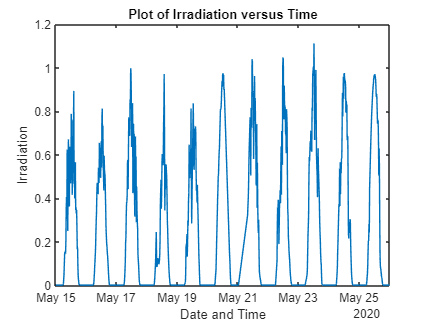

figure(1)
plot(t, irradiation);
title("Plot of Irradiation versus Time")
xlabel("Date and Time")
ylabel("Irradiation")

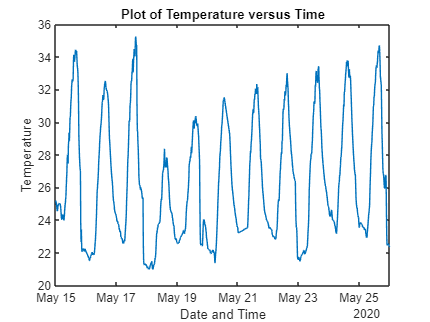


figure(2)
plot(t, temperature);
title("Plot of Temperature versus Time")
xlabel("Date and Time")
ylabel("Temperature")

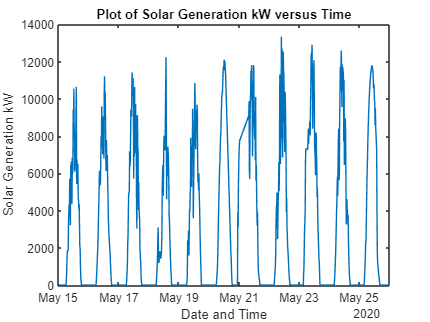


figure(3)
plot(t, generation);
title("Plot of Solar Generation kW versus Time")
xlabel("Date and Time")
ylabel("Solar Generation kW")

Correlation Trend Analysis

corrcoef(irradiation,generation)

ans =     1.0000    0.8575
    0.8575    1.0000


corrcoef(temperature,generation)

ans =     1.0000    0.4816
    0.4816    1.0000


We plot the two variables that gives the highest correlation. 

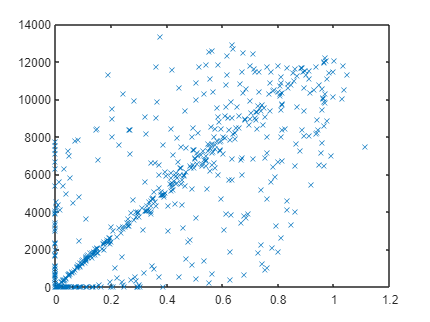

plot(irradiation, generation, 'x')

**Power Generation due to total Irradition detected in the Region**

Linear Regression Model y = a*x + b

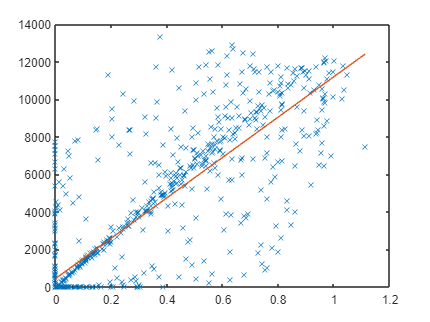

x = irradiation;
y = generation;

p = polyfit(x,y,1); % [a b] for ax+b in first-order
ypred = polyval(p,x);

plot(x,y,'x'); hold on;
plot(x,ypred); hold off;

rmse = sqrt(mean((ypred-y).^2))

rmse = 2.0150e+03

rrmse = rmse/mean(y)

rrmse = 0.6690

Polynomial Regression

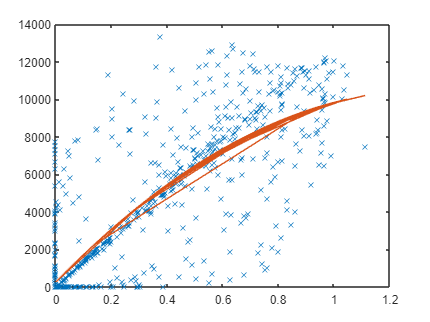

p = polyfit(x,y,2); % [a b] for ax+b in first-order
ypred = polyval(p,x);

plot(x,y,'x'); hold on;
plot(x,ypred); hold off;

rmse = sqrt(mean((ypred-y).^2))

rmse = 1.9696e+03

rrmse = rmse/mean(y)

rrmse = 0.6539

Feature Normalization

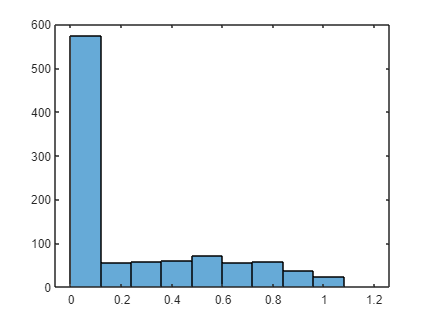

histogram(x,10)

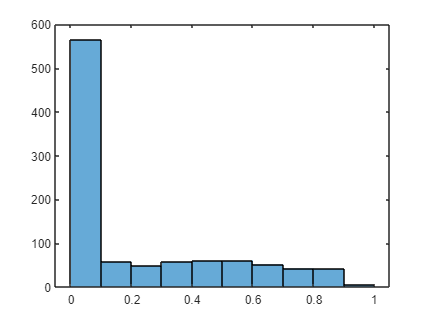


xnorm = (x - min(x))/(max(x)-min(x));
histogram(xnorm, 10);

Polynomial Regression with normalized feature

p = polyfit(xnorm,y,2);
ypred = polyval(p,xnorm);
plot(x,y,'x'); hold on;
plot(x,ypred); hold off;

rmse = sqrt(mean((ypred-y).^2))

rmse = 1.9696e+03

rrmse = rmse/mean(y)

rrmse = 0.6539

Effect of advancing to higher order of polynomial

maxdegree = 20;
for i = 1:maxdegree
    p = polyfit(xnorm,y,i);
    ypred = polyval(p,xnorm);
    error(i) = sqrt(mean((ypred-y).^2));
end

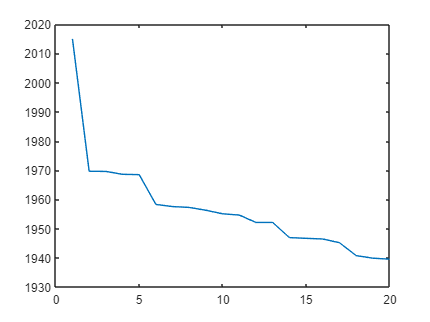


plot(1:maxdegree, error)

Split the dataset into training and validation sets

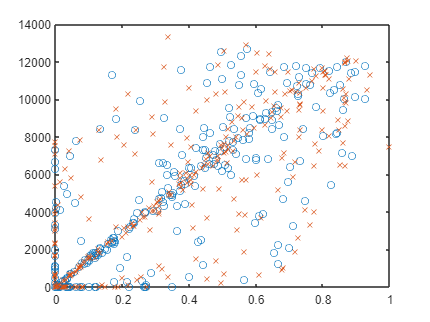

P = 0.5;
m = length(xnorm);
idx = randperm(m);
xtrain = xnorm(idx(1:round(P*m)));
xvalid = xnorm(idx(round(P*m)+1:end));
ytrain = y(idx(1:round(P*m)));
yvalid = y(idx(round(P*m)+1:end));

plot(xtrain,ytrain,'o'); hold on;
plot(xvalid,yvalid, 'x'); hold off;

Retrain a quadratic model with training/validation split

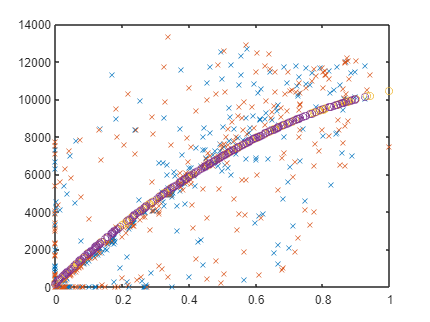

p = polyfit(xtrain,ytrain,2);
ypredtrain = polyval(p,xtrain);
ypredvalid = polyval(p,xvalid);

plot(xtrain,ytrain,'x'); hold on;
plot(xvalid,yvalid, 'x'); 
plot(xvalid,ypredvalid,'o');
plot(xtrain,ypredtrain, 'o'); hold off;

Effect of advancing to higher order (for training/validation sets)

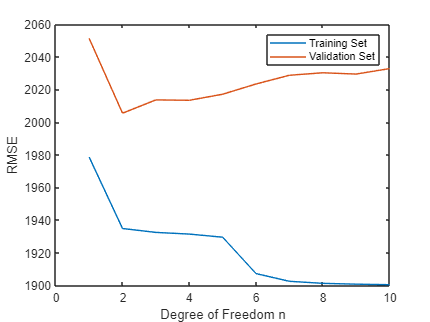

P = 0.50;
maxdegree = 10;

idx = randperm(m);
xtrain = xnorm(idx(1:round(P*m)));
xvalid = xnorm(idx(round(P*m)+1:end));
ytrain = y(idx(1:round(P*m)));
yvalid = y(idx(round(P*m)+1:end));

for i = 1:maxdegree
    p = polyfit(xtrain, ytrain, i);
    ypredtrain = polyval(p,xtrain);
    ypredvalid = polyval(p,xvalid);
    errortrain(i) = sqrt(mean((ypredtrain - ytrain).^2));
    errorval(i) = sqrt(mean((ypredvalid - yvalid).^2));
end

plot(1:maxdegree, errortrain, 1:maxdegree, errorval);
legend("Training Set", "Validation Set")
ylabel("RMSE")
xlabel("Degree of Freedom n")

Iterations on different training/test splits

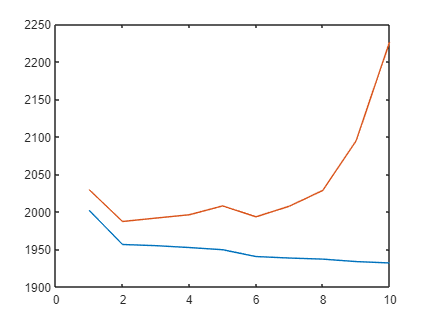

P = 0.50;
maxdegree = 10;
nrepeats = 100;
errortrain = zeros(maxdegree,1);
errorval = zeros(maxdegree,1);

for k = 1:nrepeats
    % random training/validation split
    idx = randperm(m);
    xtrain = xnorm(idx(1:round(P*m)));
    xvalid = xnorm(idx(round(P*m)+1:end));
    ytrain = y(idx(1:round(P*m)));
    yvalid = y(idx(round(P*m)+1:end));

    % loop on polynomial degrees
    for i = 1:maxdegree
        p = polyfit(xtrain, ytrain, i);
        ypredtrain = polyval(p,xtrain);
        ypredvalid = polyval(p,xvalid);
        errortrain(i) = errortrain(i) + sqrt(mean((ypredtrain - ytrain).^2));
        errorval(i) = errorval(i) + sqrt(mean((ypredvalid - yvalid).^2));
    end

end

errortrain = errortrain/nrepeats;
errorval = errorval/nrepeats;

plot(1:maxdegree, errortrain); hold on;
plot(1:maxdegree, errorval); hold off;


% Optimal Polynomial degree
[M,Order] = min(errorval)

M = 1.9872e+03

Order = 2

Creating Future Dates and Random Prediction

% Define the time range
start_time = datetime(2020, 5, 26, 0, 15, 0); % Start time
end_time = datetime(2020, 5, 26, 0, 7440, 0); % End time

% Generate the datetime array with 15-minute intervals
time = start_time : minutes(15) : end_time;
time = time';

% Generate random data for predx (replace with your actual data)
m = length(time);
xnorm1 = rand(m, 1); 

% Randomly permute the data
P = 0; % Replace with your desired value for P
idx = randperm(m);
predx = xnorm1(idx(round(P*m)+1:end));


% Set irradiance values to zero between 18:45 and 05:30 for every day
for i = 1:numel(time)
    if (time(i).Hour >= 18 && time(i).Minute >= 45) || (time(i).Hour < 5 || (time(i).Hour == 5 && time(i).Minute <= 30))
        predx(i) = 0;
    end
end

Now, we predict the Renewable Generation in future time based on irradiance

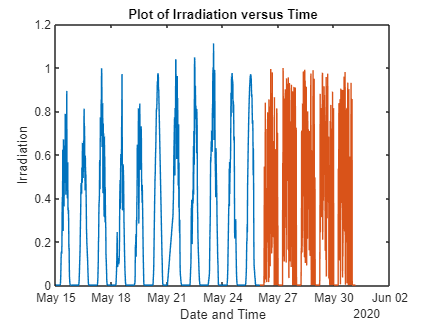

p = polyfit(xnorm,y,2);
genfuturenorm = (predx - min(x))/(max(x)-min(x));
genfuture = polyval(p,genfuturenorm);

plot(t, irradiation); hold on;
plot(time, predx); hold off;
title("Plot of Irradiation versus Time")
xlabel("Date and Time")
ylabel("Irradiation")

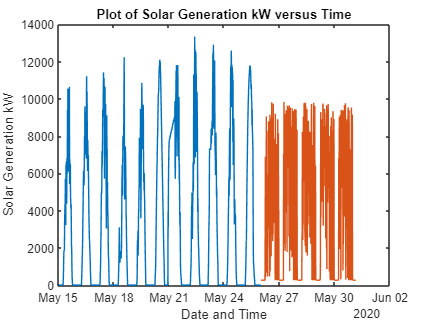


plot(t, generation); hold on;
plot(time, genfuture); hold off;
title("Plot of Solar Generation kW versus Time")
xlabel("Date and Time")
ylabel("Solar Generation kW")

Writing an Excel Data Output Reference for JSON Response

xlswrite('GenerationForecasts.xlsx', {'Time','Measured Irradiance','Measured Solar Generation','Future Time','Future Irradiance','Future Generation'}, 'Sheet1','A1')
xlswrite('GenerationForecasts.xlsx', cellstr(t), 'Sheet1','A2');
xlswrite('GenerationForecasts.xlsx', x, 'Sheet1','B2');
xlswrite('GenerationForecasts.xlsx', y, 'Sheet1','C2');
xlswrite('GenerationForecasts.xlsx', cellstr(time), 'Sheet1','D2');
xlswrite('GenerationForecasts.xlsx', predx, 'Sheet1','E2');
xlswrite('GenerationForecasts.xlsx', genfuture, 'Sheet1','F2');